# DeepInterpolation - Tiny Ephys Training Example

This example shows transfer learning on a pre-trained deep interpolation model in MATLAB for tiny ephys sample data.

## Run setup for initialization of path

setup;

## Import and Assemble Model

Import the trained model.

importednet = importKerasLayers('2020_02_29_15_28_unet_single_ephys_1024_mean_squared_error-1050.h5','ImportWeights',true);

deepinterpnet = assembleNetwork(importednet)

deepinterpnet =   DAGNetwork with properties:

         Layers: [33×1 nnet.cnn.layer.Layer]
    Connections: [36×2 table]
     InputNames: {'input_1'}
    OutputNames: {'RegressionLayer_conv2d_10'}

## Analyze Network

Optionally analyze the network

if true
    analyzeNetwork(deepinterpnet)
end


## Import Sample Ephys 

raw_data = memmapfile('ephys_tiny_continuous.dat2','Format','int16','Writable',true)

raw_data =     Filename: '/Users/vanhoosr/Documents/MATLAB/tools/DeepInterpolation-MATLAB/sampleData/ephys_tiny_continuous.dat2'
    Writable: true
      Offset: 0
      Format: 'int16'
      Repeat: Inf
        Data: 19200000×1 int16 array

nb_probes = 384; % Number of probes
total_frame_per_movie = fix(length(raw_data.Data)/(nb_probes));

%  We calculate the mean and std of the data
local_data = single(raw_data.Data);
local_mean = mean(local_data);
local_std = std(local_data);


shape = [total_frame_per_movie, fix(nb_probes / 2), 2];
% shape = [nb_probes, 2, total_frame_per_movie]; % final shape of the data [384,2,x]

% Format the data to match the dimensions of a neuropixels probe
raw_data = memmapfile('ephys_tiny_continuous.dat2','Format',{'int16', shape,'x'},'Writable',true)

raw_data =     Filename: '/Users/vanhoosr/Documents/MATLAB/tools/DeepInterpolation-MATLAB/sampleData/ephys_tiny_continuous.dat2'
    Writable: true
      Offset: 0
      Format: {'int16' [50000 192 2] 'x'}
      Repeat: Inf
        Data: 1×1 struct array with fields:
                x

ephys = raw_data.Data.x; 


#### We reorganize to follow true geometry of probe for convolution

        
pre_post_omission = 1; % Number of frames omitted before and after the inferred frame

pre_frame = 30;  % Number of frames provided before the inferred frame
post_frame = 30; % Number of frames provided after the inferred frame

batch_size = 100;

start_frame = 100;
val_endFrame = 2000; % this is the last frame to be used for validation
train_endFrame = 7000; % this is the last frame to be used for training
last_frame = 7500; % this is the last frame to be used for testing
% we are going to reorganize both the training and testing data together
% and split them later

input_full = single(zeros(nb_probes, 2, pre_frame + post_frame,batch_size));
output_full = single(zeros(nb_probes, 2,1,batch_size));


for index_frame = start_frame:last_frame
    
    
    input_index = (index_frame - pre_frame - pre_post_omission) : (index_frame + post_frame + pre_post_omission );

    input_index = input_index(input_index ~= index_frame);  % drop the predicted frame 

    for index_padding = 1: pre_post_omission % drop pre_post_omission number of frames surrounding the predicted frame
        input_index = input_index(input_index ~= index_frame - index_padding);
        input_index = input_index(input_index ~= index_frame + index_padding);
    end

    data_img_input = ephys(input_index, :, :);
    data_img_output = ephys(index_frame, :, :);
    
    
    data_img_input = permute(data_img_input,[2,3,1]); % [192,2,60]
    data_img_output = permute(data_img_output,[2,3,1]); % [192,2,1]
    
    % normalize the input and target frames
    data_img_input = (single(data_img_input) - local_mean) / local_std; 
    data_img_output = (single(data_img_output) - local_mean) / local_std;
    
    % alternating filling with zeros padding
    odd = 1: 2: nb_probes;
    even = odd + 1;
    
    input_full(odd, 1, :, index_frame-start_frame+1) = data_img_input(:, 1, :);
    input_full(even, 2, :, index_frame-start_frame+1) = data_img_input(:, 2, :);
    
    output_full(odd, 1, 1, index_frame-start_frame+1) = data_img_output(:, 1, :);
    output_full(even, 2, 1, index_frame-start_frame+1) = data_img_output(:, 2, :);

end     

## Train the network

The network expects an input of size:

net_size = importednet.Layers(1).InputSize

net_size =    384     2    60


The size of the ephys data is:

ephyssz = size(input_full(:,:,:,val_endFrame+1:train_endFrame)) % keep last (end-frame - train_endFrame) samples for testing at the end

ephyssz =          384           2          60        5000


Train for prediction (inference) with an equivalent size:

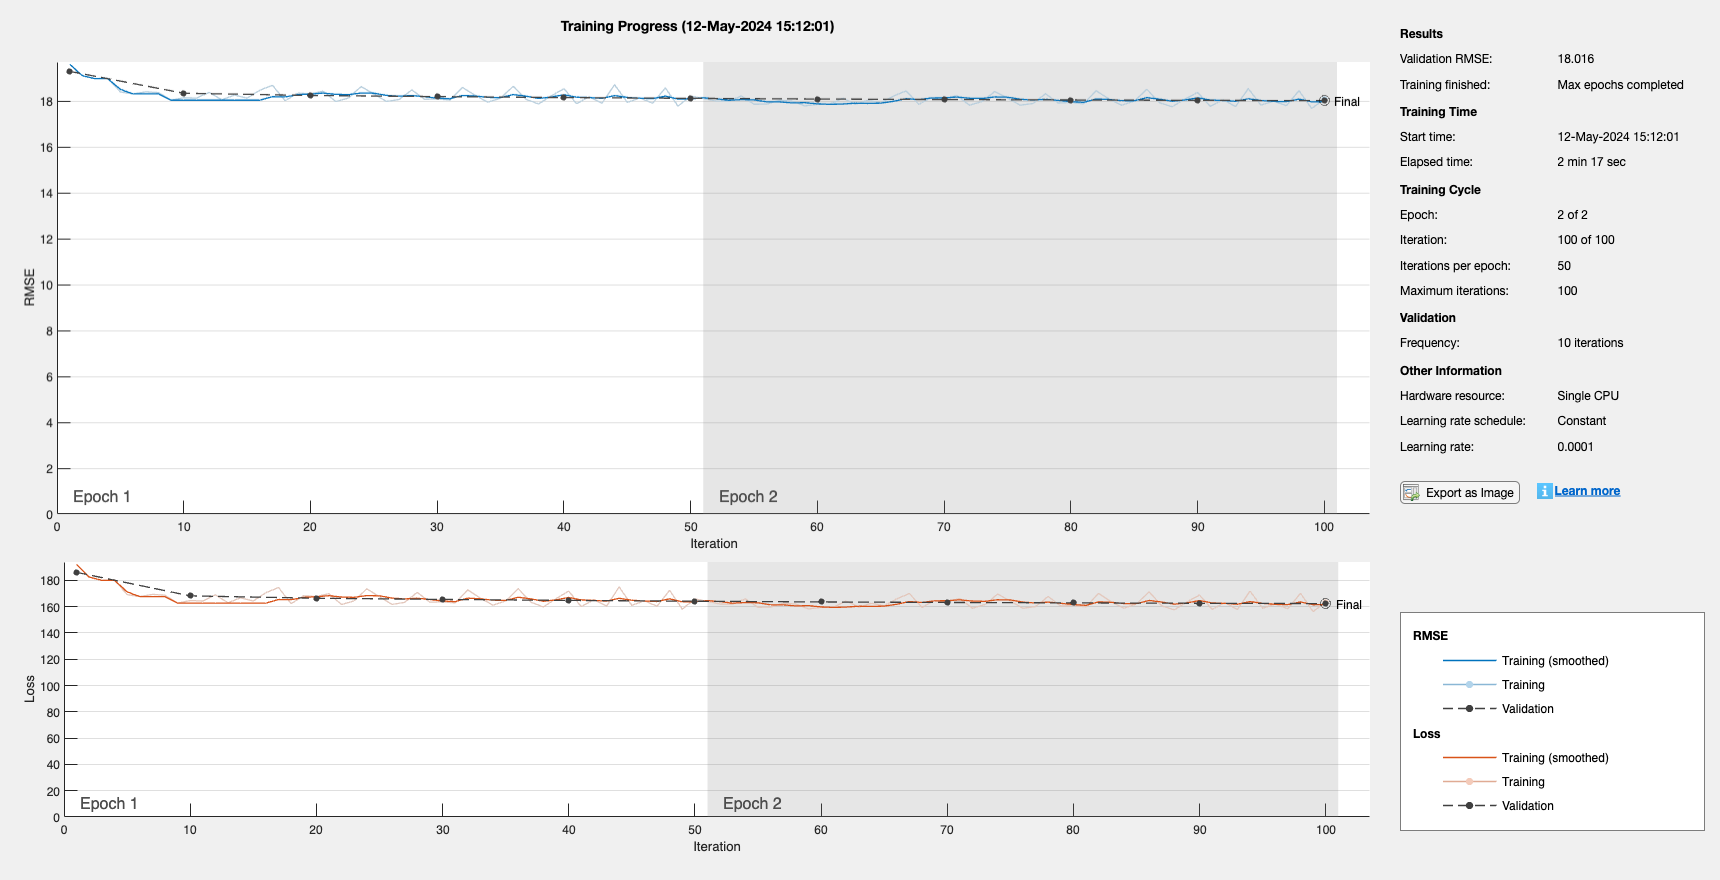

input_train = input_full(:,:,:,val_endFrame+1:train_endFrame);
target_train = output_full(:,:,:,val_endFrame+1:train_endFrame);
options = trainingOptions('adam', ...
    'MaxEpochs',2,...
    'InitialLearnRate',0.0001, ...
    'MiniBatchSize',batch_size, ...
    'Shuffle','never', ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'ValidationFrequency',10, ...
    'ValidationData',{input_full(:,:,:,1:val_endFrame),output_full(:,:,:,1:val_endFrame)});

try
    transfer_train_model = trainNetwork(input_train,target_train,importednet,options);
    
    
catch
    warning('Error using trainNetwork. Returning null.');
    transfer_train_model = [];
end

## Use the trained network for inference

Take samples excluding training data

num_frames = 100; % read 100 frames after the training data
% start_frame = train_endFrame+1;

**Choose the start index of the frames to be predicted**

beg_frame = ceil(7100); 

end_frame = beg_frame+num_frames-1; 
input_infer = input_full(:,:,:,beg_frame:end_frame); 
target_infer = output_full(:,:,:,beg_frame:end_frame); 

**Run inference**

try
    ephys_pred = predict(transfer_train_model,input_infer);
    ephys_pred = permute(ephys_pred,[4,1,2,3]);
    target_infer = permute(target_infer,[4,1,2,3]);
    disp('Output size = ')
    disp(size(ephys_pred));

    
catch
    warning('Error using predict. Returning null.');
    ephys_pred = [];
end

Output size = 


   100   384     2


## Plot inference results

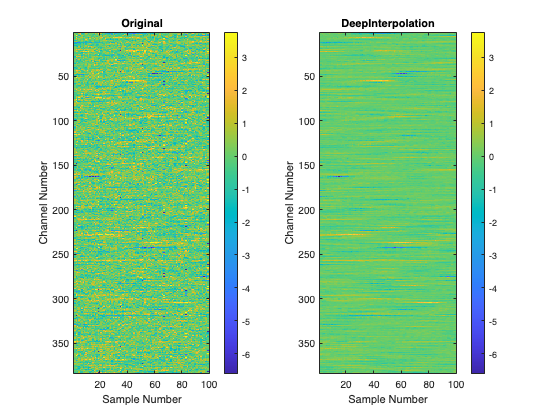


target_frames = zeros(num_frames,nb_probes);
pred_frames = zeros(num_frames,nb_probes);

% we had earlier filled half of the channels with zeros to match probe geometry
% now we take only the non-zero channels and combine the 2 columns of neuropixels into 1 

target_frames(:,1:fix(nb_probes/2)) = target_infer(:,odd,1);
target_frames(:,(fix(nb_probes/2)+1):nb_probes) = target_infer(:,even,2);

pred_frames(:,1:fix(nb_probes/2)) = ephys_pred(:,odd, 1);
pred_frames(:,(fix(nb_probes/2)+1):nb_probes) = ephys_pred(:,even, 2);


hFig = figure; 
hAxRef = subplot(1,2,1); 
hImRef = imagesc(target_frames'); 
hAx = subplot(1,2,2); 
hIm = imagesc(hAx,pred_frames'); 
set(hAxRef,'CLim',hAx.CLim)
subplot(1,2,1)
colorbar
xlabel('Sample Number')
ylabel('Channel Number')
title('Original')
subplot(1,2,2)
colorbar
xlabel('Sample Number')
ylabel('Channel Number')
title('DeepInterpolation')

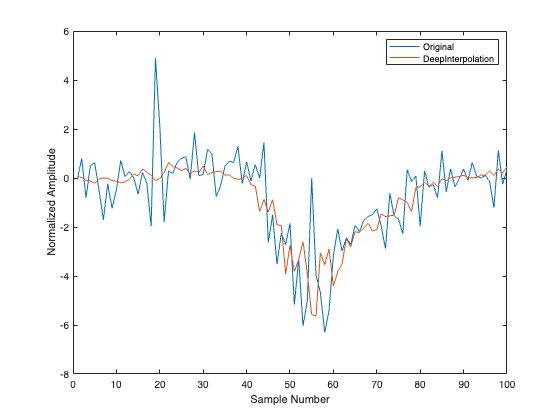

figure
channel =242; % choose a channel to plot
plot(target_frames(:,channel))
hold on
plot(pred_frames(:,channel))
legend('Original','DeepInterpolation')
xlabel('Sample Number')
ylabel("Normalized Amplitude")